# 5 bars Robot Direct

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all

l1=50; 
l2=100;  % link length
h=150;
l0 =50;
L=[h; l0; l1; l2]';

g1=l1/2;  g2=l1/2; % link1
g3=l2/2;  g4=l2/2; %link2

G=[g1; g2; g3; g4]';

m1 = 10; % link1
m2 = 3; %link2
m_gripper = 1; % gripper
Jg1=0.03; % MoI link1
Jg2=0.03; % MoI link2
Jg = 0.01; % MoI gripper

M = diag([(m_gripper/2),(m_gripper/2),m2,m2,(Jg+Jg2),m1,m1,Jg1,m1,m1]);

S0=[-25;80];  % gripper first position
S1=[75;50];     % gripper final position

dS = S1 - S0;
T = 5;
n = 100;
dT = T/(n-1);


### 2) The robot moves linearly in joint coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


close all
figure(1)

Plot the workspace

% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

Plot the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


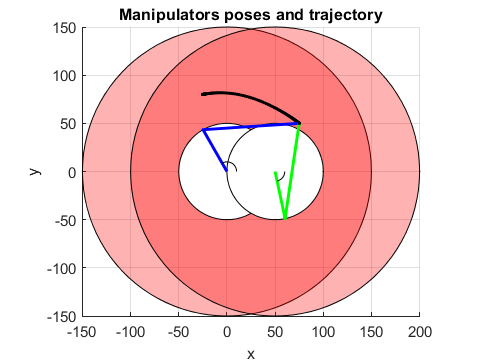

Q_ini = inverse_kinematics(S0,L,[130*pi/180 50*pi/180]);
Q_fin = inverse_kinematics(S1,L,[130*pi/180 50*pi/180]);

dQ = Q_fin - Q_ini;

for i = 1:n
    t = (i-1)*dT;
    tt(i) = t;
    [q(i,:) qp(i,:) qpp(i,:)] = cycloidal(t,T,Q_ini,dQ);
    
    if i==1
        guess = [0 80];
    else
        guess = s(i-1,:);
    end
    
    s(i,:) = direct_kinematics(q(i,:),L,guess);
    [J, J_s, J_q] = Jacobian(s(i,:),q(i,:),L);
    v(i,:) = inv(J)*qp(i,:)';
    a(i,:) = -inv(J_s)*(Jp_s(q(i,:),qp(i,:),v(i,:),L)*v(i,:)'+Jp_q(s(i,:),q(i,:),qp(i,:),v(i,:),L)*qp(i,:)'+J_q*qpp(i,:)');

    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));

    plot(s(i,1),s(i,2),'.-black')
    % Plot the angle arc
    h1 = plotAngleArc([0,0],10,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],10,[0,q(i,2)],'k-',1); %beta

    pause(dT)
    if i==n
        break
    end
    delete(config1); delete(config2); delete(h1); delete(h2);
    hold off
    title('Manipulators poses and trajectory');
    xlabel('x')
    ylabel('y')
end

hold off

### Print $\alpha ,\beta ,\gamma \;$and $\theta$

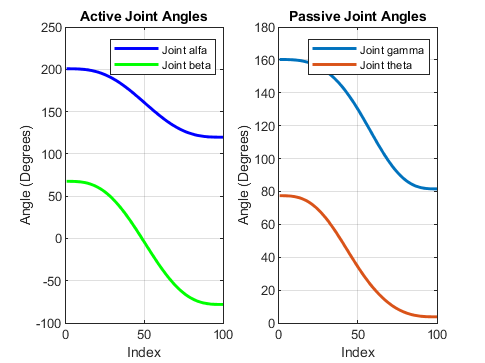

figure(2)
% alpha e beta
subplot(1,2,1)
plot(q(:,1)*180/pi,'b','LineWidth',2)
hold on
plot(q(:,2)*180/pi,'g','LineWidth',2)
hold off
title('Active Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint alfa','Joint beta')

% gamma e theta
subplot(1,2,2)
plot(gamma*180/pi,'LineWidth',2)
hold on
plot(theta*180/pi,'LineWidth',2)
hold off
title('Passive Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint gamma','Joint theta')

### Joint motion

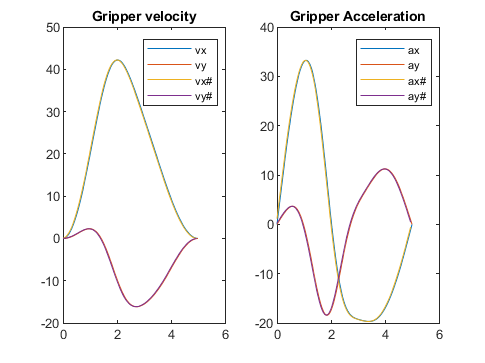

figure(3)
v_x_debug = diff(s(:,1))/dT;
v_y_debug = diff(s(:,2))/dT;

a_x_debug = diff(v(:,1))/dT;
a_y_debug = diff(v(:,2))/dT;

subplot(1,2,1)
plot(tt,v(:,1),tt,v(:,2),tt(1:end-1),v_x_debug,tt(1:end-1),v_y_debug)
legend('vx','vy','vx#','vy#');
title("Gripper velocity")

subplot(1,2,2)
plot(tt,a(:,1),tt,a(:,2),tt(1:end-1),a_x_debug,tt(1:end-1),a_y_debug)
legend('ax','ay','ax#','ay#')
title('Gripper Acceleration')